# Systems Lab: Systems of ODEs in MATLAB

## Student Information

## Exercise 1

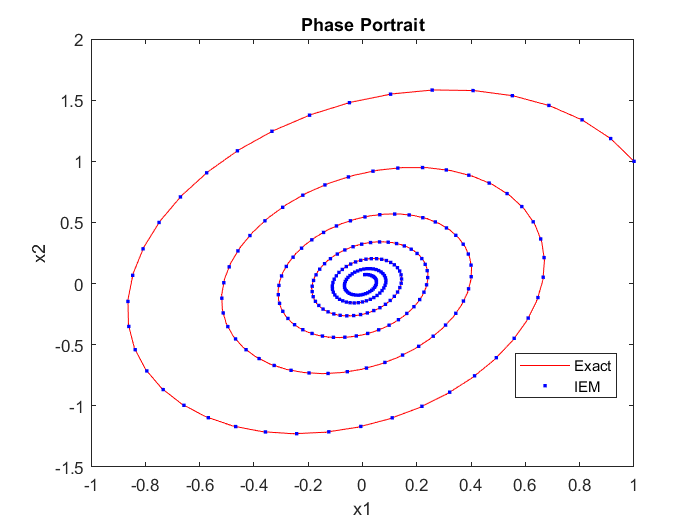

f1 = @(t,x1,x2) 0.5*x1-2*x2;
f2 = @(t,x1,x2) 5*x1-x2;
x0 = [1,1];
t0 = 0; tN = 4*pi; h=0.05;

[t, x1, x2] = solvesystem_wuqingy6(f1, f2, t0, tN, x0, h);

x1_exact = exp(-t/4).*cos(sqrt(151)/4*t) - 5/sqrt(151)*exp(-t/4).*sin(sqrt(151)/4*t);
x2_exact = exp(-t/4).*(3/8*cos(sqrt(151)/4*t) + sqrt(151)/8*sin(sqrt(151)/4*t)) - 5/sqrt(151)*exp(-t/4).*(-sqrt(151)/8*cos(sqrt(151)/4*t)+3/8*sin(sqrt(151)/4*t));
plot(x1_exact,x2_exact, "r");

hold on;
plot(x1, x2, ".b");
title("Phase Portrait");
xlabel("x1");
ylabel("x2");
legend("Exact", "IEM","location","best");
hold off;

## Exercise 2

Objective: Compare Heun with an exact solution

Details: Consider the system of ODEs

`x1' = x1/2 - 2*x2, x2' = 5*x1 - x2`

with initial condition `x(0)=(1,1)`.

## Exercise 3

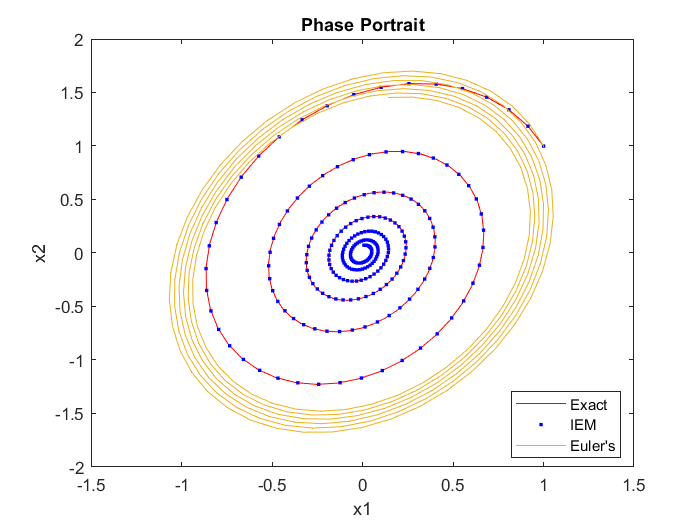

f1 = @(t,x1,x2) 0.5*x1-2*x2;
f2 = @(t,x1,x2) 5*x1-x2;
x0 = [1,1];
t0 = 0; tN = 4*pi; h=0.05;


[t, x1, x2] = solvesystem_wuqingy6(f1, f2, t0, tN, x0, h);

x1_exact = exp(-t/4).*cos(sqrt(151)/4*t) - 5/sqrt(151)*exp(-t/4).*sin(sqrt(151)/4*t);
x2_exact = exp(-t/4).*(3/8*cos(sqrt(151)/4*t) + sqrt(151)/8*sin(sqrt(151)/4*t)) - 5/sqrt(151)*exp(-t/4).*(-sqrt(151)/8*cos(sqrt(151)/4*t)+3/8*sin(sqrt(151)/4*t));
plot(x1_exact,x2_exact, "r");

hold on;
plot(x1, x2, ".b");

% iode
times = t0:h:tN;

f = @(t,x) [0.5.*x(1)-2.*x(2); 5.*x(1)-x(2)];
x0 = [1;1];
t0 = 0; tN = 4*pi; h=0.05;

result = euler(f, x0, times);
plot(result(1,:), result(2,:));

title("Phase Portrait");
xlabel("x1");
ylabel("x2");
legend("Exact", "IEM","Euler's", "location","best");
hold off;


% Exact solution:
% x1 = exp(-t/4).*cos(sqrt(151)/4*t) - 5/sqrt(151)*exp(-t/4).*sin(sqrt(151)/4*t);
% x2 = exp(-t/4).*(3/8*cos(sqrt(151)/4*t) + sqrt(151)/8*sin(sqrt(151)/4*t))
% - 5/sqrt(151)*exp(-t/4).*(-sqrt(151)/8*cos(sqrt(151)/4*t)+3/8*sin(sqrt(151)/4*t));

% Differences: Euler's method diverges from both the exact solution
% and the IEM right after the initial value (1,1). This is because Euler's
% Method is a purely linearly approximation but the spirals keep going in
% and approach (0,0). Euler's Method will never "catch up".

## Exercise 4

4.1. `dx/dt = [2 1; 1 3] x`

4.2. `dx/dt = [-2 -1; -1 -3] x`

4.3. `dx/dt = [-4 -6; 3 5] x`

4.4. `dx/dt = [4 6; -3 -5] x`

4.5. `dx/dt = [0 -1; 1 -1] x`

4.6. `dx/dt = [0 1; -1 1] x`

4.7. `dx/dt = [2 8; -1 -2] x`

4.8. `dx/dt = [-2 -8; 1 2] x`

4.9. `dx/dt = [-8 5; -13 8] x`

4.10. `dx/dt = [8 -5; 13 -8] x`